**Exercise 6:**

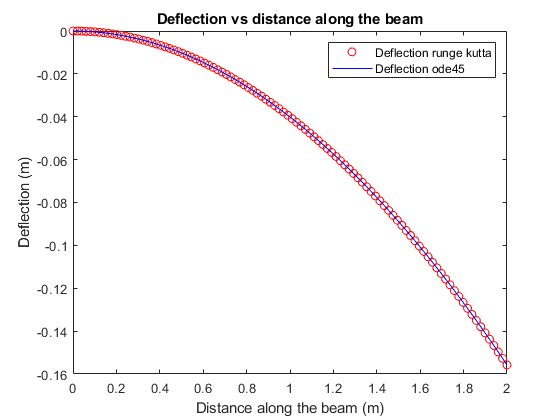

bc = [0; 0];
t=linspace(0,2);
func=@odesyst;
[a,b] = ode45(func,t,bc);

yode45 = b(:,1);
dydxode45 = b(:,2);

[results]=runge_kutta(func,t,bc);
y = results(1,:);
dydx = results(2,:);

plot(t,y,'ro',t,yode45,'b')
title('Deflection vs distance along the beam')
legend('Deflection runge kutta','Deflection ode45')
xlabel('Distance along the beam (m)')
ylabel('Deflection (m)')

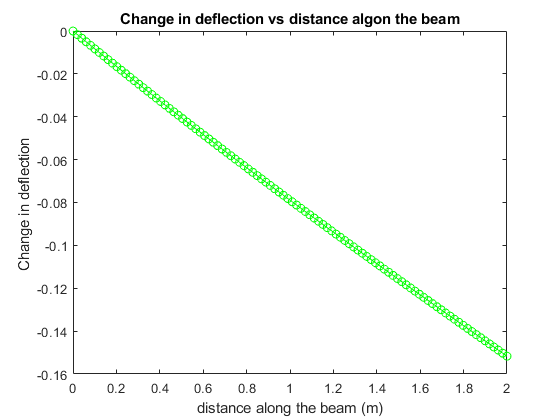


plot(t,dydx,'go',t,dydxode45,'g')
title('Change in deflection vs distance algon the beam')
xlabel('distance along the beam (m)')
ylabel('Change in deflection ')

function [dydx] = odesyst(t,y)
L=2; rhog=100; EI=2400;

dydx = zeros(2,1);


dydx(1) = y(2); % dydx

dydx(2) = (1/EI)*(-rhog*sqrt( (1+(y(2)))^3)*(y(1)*(y(1)-L/2)+(L^2/2)));%d^2y/dx^2

end

function [y] = runge_kutta(df,x,y0)
m = length(y0);
n = length(x);
% y is a matrix of size 'mxn'
y=zeros(m,n);
y(:,1)=y0;
for i=1:n-1
    h = x(i+1)-x(i);
    xi=x(i);
    yi=y(:,i);
    k1 = feval(df,xi,yi);
    k2 = feval(df,xi+0.5*h,yi+0.5*k1*h);
    k3 = feval(df,xi+0.5*h,yi+0.5*k2*h);
    k4 = feval(df,xi+h,yi+k3*h);
    y(:,i+1) = y(:,i) + h*(k1+2*k2+2*k3+k4)/6;
end
end